rng('default')
filename = "lessonlearned.csv";
data = readtable(filename,'TextType','string'); 
head(data)

ans = 8×6 table
       Time       event_id                event_type                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                                abstract                                                                                                                                                                                                                                                                                                                                                        

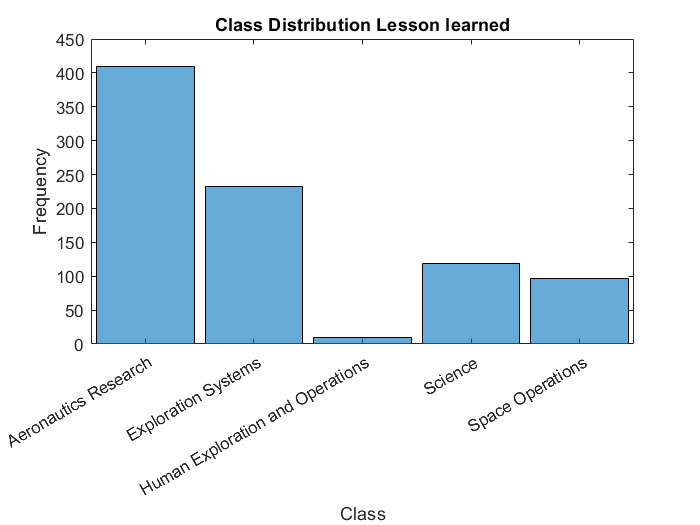

idx = strlength(data.event_narrative) == 0;
data(idx,:) = [];
idx2 = strlength(data.abstract) == 0;
data(idx2,:) = [];
data.event_type = categorical(data.event_type);
figure
h = histogram(data.event_type);
xlabel("Class")
ylabel("Frequency")
title("Class Distribution Lesson learned")

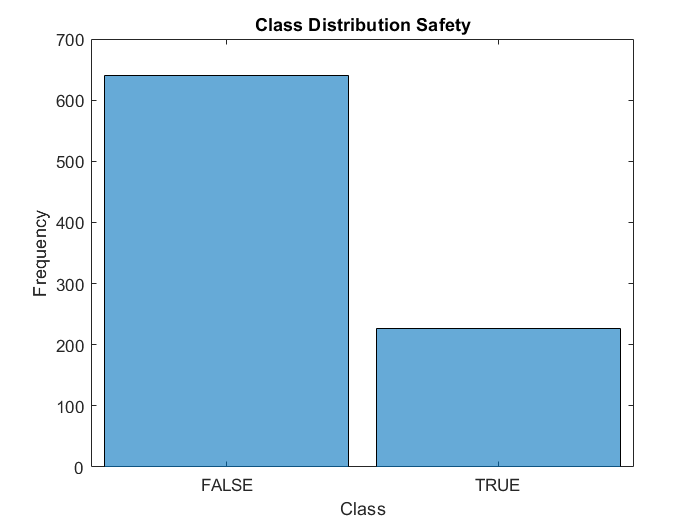


data.safety = categorical(data.safety);
figure
h2 = histogram(data.safety);
xlabel("Class")
ylabel("Frequency")
title("Class Distribution Safety")

classCounts = h.BinCounts;
classNames = h.Categories;

classCounts2 = h2.BinCounts;
classNames2 = h2.Categories;

idxLowCounts = classCounts < 10;
infrequentClasses = classNames(idxLowCounts);
idxInfrequent = ismember(data.event_type,infrequentClasses);
data(idxInfrequent,:) = [];

idxLowCounts2 = classCounts2 < 10;
infrequentClasses2 = classNames2(idxLowCounts2);
idxInfrequent2 = ismember(data.safety,infrequentClasses);
data(idxInfrequent2,:) = [];
cvp = cvpartition(data.event_type,'Holdout',0.1);
cvp2 = cvpartition(data.safety,'Holdout',0.1);
dataTrain = data(cvp.training,:);
dataTest = data(cvp.test,:);

textDataTrain = dataTrain.event_narrative;
textDataTest = dataTest.event_narrative;
YTrain = dataTrain.event_type;
YTest = dataTest.event_type;

textDataTrain2 = dataTrain.abstract;
textDataTest2 = dataTest.abstract;
YTrain2 = dataTrain.safety;
YTest2 = dataTest.safety;

documents = preprocessLessonLearned(textDataTrain);
documents(1:5)

ans =   5×1 tokenizedDocument:

    113 tokens: laboratory testing reveal high anticipate safety risk potential arcflash event manhole environment conduct kscês unreduced fault current level safety risk include bright flash excessive sound smoke due finding absence mitigation install time manhole entry require full arcflash ppe furthermore manhole entry temporarily restrict short duration inspection further mitigation implement installation neutral grounding resistor ngrs substation transformer flash sound flame energy reduce hazard reduction substantial require ppe less cumbersome enable effective performance maintenance task energized configuration ngr install surge arrester currently ksc design load fail fault cause secondary outage increase repair time replacement surge arrester conduct year due result hundred facility outage impact surge suppressor upgraded ngrs manhole construction maintenance operation app

documents2 = preprocessLessonLearned(textDataTrain2);
documents2(1:5)

ans =   5×1 tokenizedDocument:

    95 tokens: power system distribution kennedy space center ksc consist primarily highvoltage underground cable cable include approximately 5000 splice splice failure result arc flash event extremely hazardous personnel vicinity arc flash construction maintenance task perform effectively require personal protective equipment ppe deenergize cable feasible due cost lose productivity safety risk others implement require outage verify alternate effective mitigation arc flash testing conduct controlled environment arc flash effect great expect testing demonstrate addition neutral grounding resistor ngrs result substantial reduction arc flash effect result ngrs install ksc primary substation transformer presence ngrs enable usage less cumbersome ppe increase
    27 tokens: operator error involve misprobing safetomate procedure breakout box bob result short circuit blow fuse patch probe

bag = bagOfWords(documents)

bag =   bagOfWords with properties:

          Counts: [775×5800 double]
      Vocabulary: [1×5800 string]
        NumWords: 5800
    NumDocuments: 775


bag2 = bagOfWords(documents2)

bag2 =   bagOfWords with properties:

          Counts: [775×5196 double]
      Vocabulary: [1×5196 string]
        NumWords: 5196
    NumDocuments: 775


bag = removeInfrequentWords(bag,2);
[bag,idx] = removeEmptyDocuments(bag);
YTrain(idx) = [];
bag

bag =   bagOfWords with properties:

          Counts: [775×2485 double]
      Vocabulary: [1×2485 string]
        NumWords: 2485
    NumDocuments: 775


bag2 = removeInfrequentWords(bag2,2);
[bag2,idx] = removeEmptyDocuments(bag2);
YTrain(idx) = [];
bag2

bag2 =   bagOfWords with properties:

          Counts: [775×2250 double]
      Vocabulary: [1×2250 string]
        NumWords: 2250
    NumDocuments: 775


XTrain = bag.Counts;
mdl = fitcecoc(XTrain,YTrain,'Learners','linear')

mdl =   classreg.learning.classif.CompactClassificationECOC
      ResponseName: 'Y'
        ClassNames: [Aeronautics Research    Exploration Systems    Science    Space Operations]
    ScoreTransform: 'none'
    BinaryLearners: {6×1 cell}
      CodingMatrix: [4×6 double]


  Properties, Methods


XTrain2 = bag2.Counts;
mdl2 = fitcecoc(XTrain2,YTrain2,'Learners','linear')

mdl2 =   classreg.learning.classif.CompactClassificationECOC
      ResponseName: 'Y'
        ClassNames: [FALSE    TRUE]
    ScoreTransform: 'none'
    BinaryLearners: {[1×1 ClassificationLinear]}
      CodingMatrix: [2×1 double]


  Properties, Methods


[`templateLinear`](docid:stats_ug#bu216oi).

documentsTest = preprocessWeatherNarratives(textDataTest);
XTest = encode(bag,documentsTest);

documentsTest2 = preprocessWeatherNarratives(textDataTest2);
XTest2 = encode(bag2,documentsTest2);

YPred = predict(mdl,XTest);
acc = sum(YPred == YTest)/numel(YTest)

acc = 0.5238


YPred2 = predict(mdl2,XTest2);
acc2 = sum(YPred2 == YTest2)/numel(YTest2)

acc2 = 0.7619

str = [ ...
    "NASA is better served by including certain baseline information, data, and (at least temporary) access to the model (or model-system) as required deliverables for analysis contracts. This additional information, data, or products can provide a more concrete basis for understanding the model, its development, and use."
    "NASA policy (NPR 7120.5 and NPR 7123.1B) and guidance (NASA Systems Engineering Handbook (SP-2016-6105), Rev 2) are primarily based on the waterfall development model. Programs using the lifecycle models described in these references must be aware the providers using a different life cycle model will not conform to the NASA waterfall model. This can lead to a variety of unfulfilled expectations and design activities that happen in a different sequence and time phasing than expected by the NASA model."
    "equirements should be managed in a single tool rather than allowing projects to have a separate way of managing their requirements. Evidence of design compliance (requirements verification matrices) should also be integrated into the tool to ensure all requirements are in sync and closure evidence is available. An alternative solution is to allow the use of different tools but to ensure that these data sets remain in sync (interoperability)."];
documentsNew = preprocessWeatherNarratives(str);
XNew = encode(bag,documentsNew);
labelsNew = predict(mdl,XNew)

labelsNew = 3×1 categorical array
     Aeronautics Research 
     Aeronautics Research 
     Exploration Systems 


str2 = [ ...
    "NASA, on certain occasions, contracts for the accomplishment of M&S-based analyses with few requirements, if any, for delivery of the M&S or other development or use artifacts along with the results from the analyses.  While the costs for such contracts are lower, this practice provides an environment for potentially limiting the full and complete understanding of the model and data upon which the analyses are accomplished."
    "The Exploration Ground Systems (EGS) Program at Kennedy Space Center (KSC) experienced issues in the early phases of testing of Ground Support Equipment and other facility and support systems. These issues were related to: 1. test team having common understanding of individual roles and responsibilities; 2. Communicating problems and test status; 3. Processes used to integrate and coordinate work spanning multiple organizations; and 4. quickly dispositioning and resolving issues and returning to testing. The results of these issues included testing delays and cost growth. When performing large-scale complex testing it is important to ensure that equipment and supporting services are available before testing is initiated, roles and responsibilities are clearly understood, that the right stakeholders are involved in technical discussions and decisions, that problem resolutions and other technical decisions are made quickly and communicated clearly and that the process supports quickly returning to testing."
    "The Exploration Ground Systems Program received inputs (Review Item Discrepancies [RIDs], Requests for Action [RFAs]) and Action Items during the Critical Design Review (CDR) Life Cycle Review (LCR). Some of the RIDs and RFAs were submitted prior to and during the CDR and some inputs (such as RFAs or action items) resulted from follow-on out-briefings at higher levels in the Agency. RIDs, RFAs and action items were worked and closed with decision makers at various boards at the Program, cross-program or Agency level as appropriate. It was difficult and time-consuming to provide status information and closure evidence for all RIDs, RFAs and action items associated with the entire CDR life cycle review. This difficulty was due to the many sources of RIDs/RFAs and action items, the variety of forums at which these occurred and the period of time elapsed between close-out of the CDR and the final out-briefs at the Agency level."];
documentsNew2 = preprocessWeatherNarratives(str2);
XNew2 = encode(bag2,documentsNew2);
labelsNew2 = predict(mdl2,XNew2)

labelsNew2 = 3×1 categorical array
     FALSE 
     FALSE 
     FALSE 


function documents = preprocessLessonLearned(textData)

documents = tokenizedDocument(textData);

documents = addPartOfSpeechDetails(documents);
documents = normalizeWords(documents,'Style','lemma');

documents = erasePunctuation(documents);

documents = removeStopWords(documents);

documents = removeShortWords(documents,2);
documents = removeLongWords(documents,15);

end